% 设置参数
maxN = 60

maxN = 60

minN = 70

minN = 70

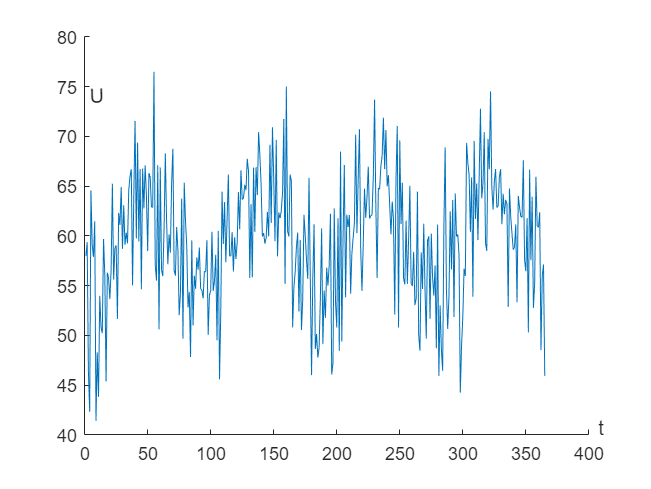

amplitude = (maxN-minN)/2;   % 振幅
n=4;
period = 365/n;          % 周期（一年n次干旱）
t = zeros([1,n]);
d = zeros([1,n]);
phi = zeros([1,n]);
for i = 1:n
    t(1,i) = (365/n) * i + randi([-10,10]); %发生时间
    d(1,i) = 20 + randi([-5,30]);          %持续时间
    phi(1,i) = 2*pi/period*(t(1,i)+d(1,i)/2); %相位
end

% 生成正弦函数数据
t = 1:4017;              % 时间范围为一年
for i = 1:n
    data = amplitude*sin(2*pi/period*t+phi(i));
end
data = data + minN +amplitude;
% 添加随机噪声
noise = normrnd(-5, 5, size(data));
data = data + noise;

% 将湿度限制在0~80范围内

% 可视化生成的数据
hold on
plot(1:365, data(1:365));
xlabel('t',"Position",[410,42]);
ylabel('U',"Position",[10,73],"Rotation",pi/2);